stockdata=readtable('stock_data.csv');
prices=table2array(stockdata(:,3:end));

corr(prices(:,1),prices(:,2));

prices(:,1);

% Finding stocks with max correlation
corrs=zeros(10);
for i=1:10
    for j=1:10
        if i==j continue; end

        corrs(i,j)=corr(prices(:,i),prices(:,j));
    end
end

% GOOG AND TTWO had highest correlation from visual inspection
GOOG=prices(:,3);
TTWO=prices(:,10);

M=60;

% Create returns vector
retGOOG=price2ret(GOOG);
retTTWO=price2ret(TTWO);
N=length(retTTWO);

% Evaluate regression coefficient
alphavec = zeros((N-60),1);
betavec = zeros((N-60),1);
for i = M+1:1:N
[beta,betaint] = regress(retGOOG((i-M):(i-1)),[ones(M,1) retTTWO((i-M):(i-1))]);
alphavec(i-M) = beta(1);
betavec(i-M) = beta(2);
end

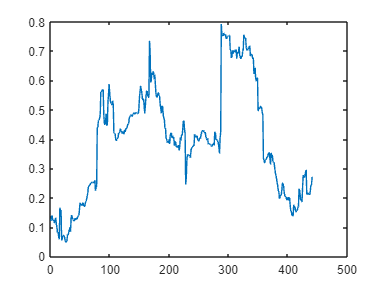

plot(betavec);

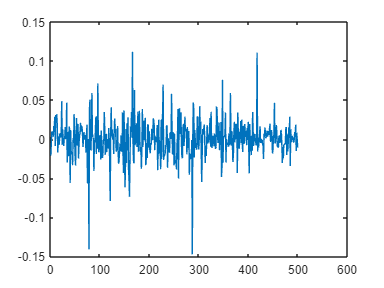

plot(retTTWO);

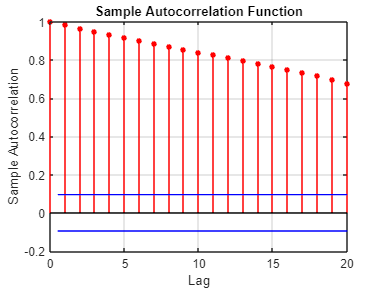

autocorr(betavec);

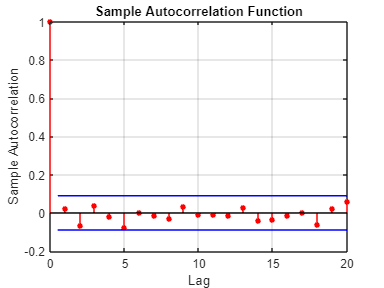

autocorr(retTTWO);